# Oblique plane wave after lens

% Jonghwan Lee, Feb 2021

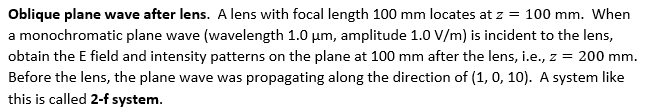

## Constants and parameters

All lengths are in [m].

clear;
f = 100e-3;  % focal length
lam = 1e-6;  % wavelength
E0 = 1.0;  % amplitude
kUnit = [1 0 10];  % wavenumber unit vector
kUnit = kUnit/norm(kUnit)  % make it be a unit vector

kUnit =     0.0995         0    0.9950


## Input E field pattern at z = 0

Propagation vector

k = 2*pi/lam*kUnit 

k = 	1.0e+06 *

    0.6252         0    6.2520


Make (x,y) grid.

dx = lam;  % details smaller than wavelength cannot be represented by paraxial wave
x = -200e-6:dx:200e-6;  nx = length(x);
y = -200e-6:dx:200e-6;  ny = length(y);
[gx,gy] = ndgrid(x,y);
size(gx)

ans =    401   401


Make the input E field pattern, E(x,y,0)

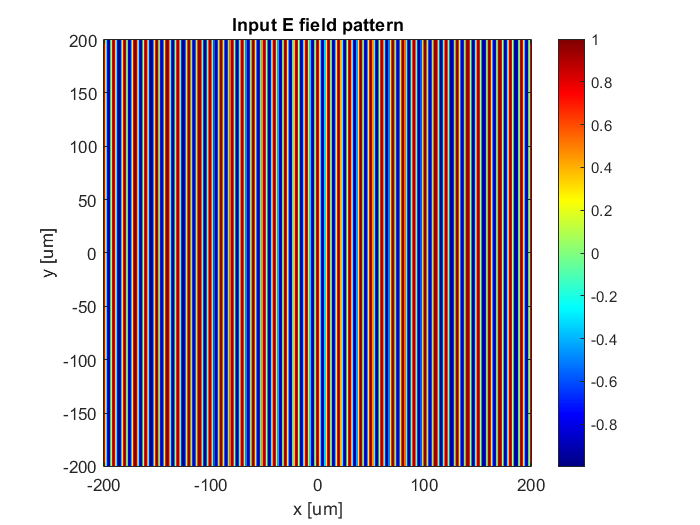

E1 = E0*exp(1i*(k(1)*gx+k(2)*gy+k(3)*0));

figure;  colormap(jet);
imagesc(x*1e6,y*1e6,real(E1)');
set(gca,'ydir','normal');
axis image;
colorbar;
xlabel('x [um]');  ylabel('y [um]');
title('Input E field pattern');

## Output E field pattern at z = 2*f

2D Fourier transform

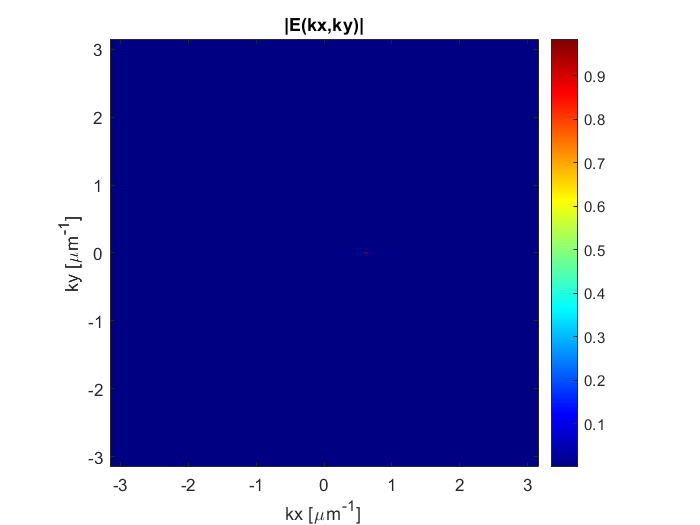

E1k = fft2(E1);  % Ein(kx,ky)
E1k = fftshift(E1k);  % move the zero-wavenumber component to the center (it is not in fft2() by default)

E1k = E1k/numel(E1k);  % for exact amplitudes, typically not necessary in FFT for imaging simulation

kmax = 2*pi/dx /2;  % /2 by Nyquist
kx = linspace(-kmax,kmax,nx);
ky = linspace(-kmax,kmax,ny);

figure;  colormap(jet);
imagesc(kx/1e6,ky/1e6,abs(E1k)');
set(gca,'ydir','normal');
axis image;
colorbar;
xlabel('kx [\mum^{-1}]');  ylabel('ky [\mum^{-1}]');
title('|E(kx,ky)|');

Plot E1(kx,0)

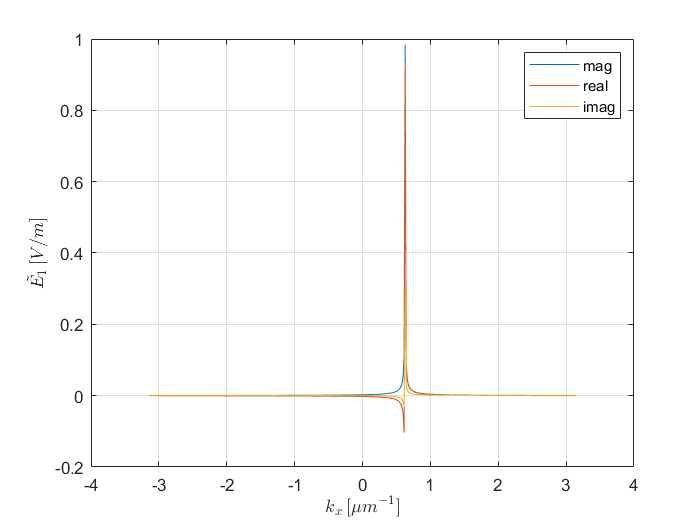

figure;
E1kx = E1k(:,round(end/2));  % E1(kx,ky=0)
plot(kx/1e6,[abs(E1kx),real(E1kx),imag(E1kx)]);
legend({'mag','real','imag'})
grid on;
xlabel('$$ k_x \, [\mu m^{-1}] $$', 'interpreter','latex');
ylabel('$$ \tilde{E_1} \, [V/m] $$', 'interpreter','latex');


[~,im] = max(abs(E1kx))

im = 241

[kx(im) k(1)]/1e6  % check if the peak kx equals the original kx, confirming the scaling of kx above

ans =     0.6283    0.6252


Substitute $k_x=\frac{k}{f}x$ for the output E field pattern $E_2(x,y,2f)$.

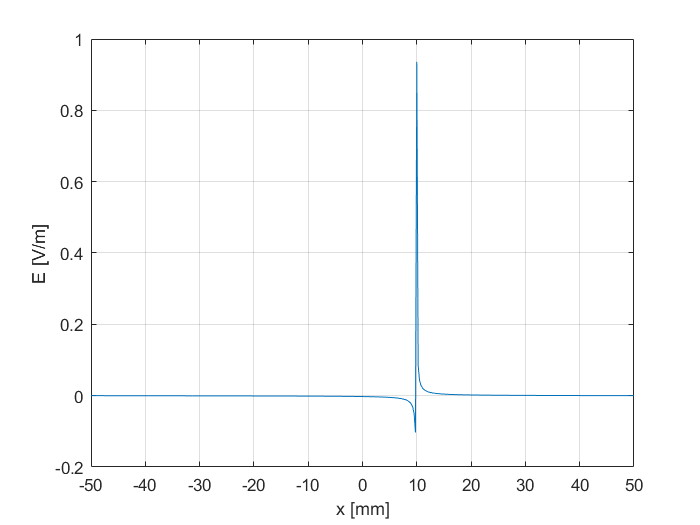

E2 = E1k;  % same values in the array
x2 = kx/norm(k)*f;  % scale the axis
y2 = ky/norm(k)*f;

figure;
E2x = E2(:,round(end/2));  % E2(x,y=0)
plot(x2*1e3,real(E2x));
grid on;
xlabel('x [mm]');
ylabel('E [V/m]'); 

- The E field magnitude is inaccurate.

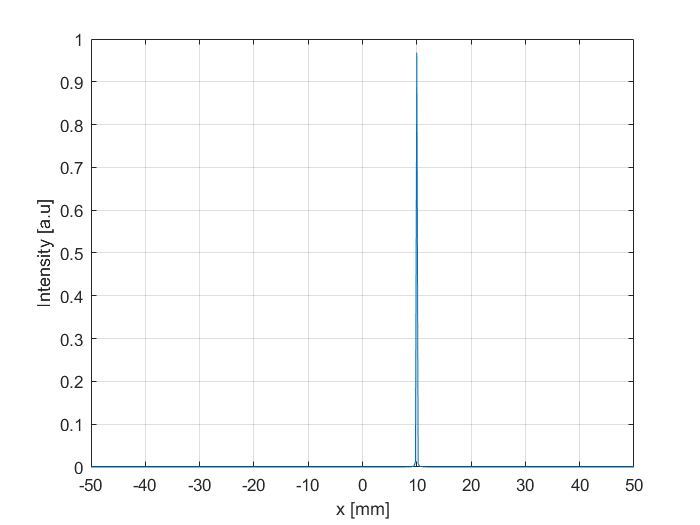

I2x = E2x.*conj(E2x);  % now only pattern matters
figure;
plot(x2*1e3,I2x);
grid on;
xlabel('x [mm]');
ylabel('Intensity [a.u]');  % arbitrary unit


[~,im] = max(I2x);  % max intensity
[x2(im) k(1)/norm(k)*f]  % check if the peak x (focused position) equals the true focus position we know

ans =     0.0100    0.0100


Plot the image at the focal plane

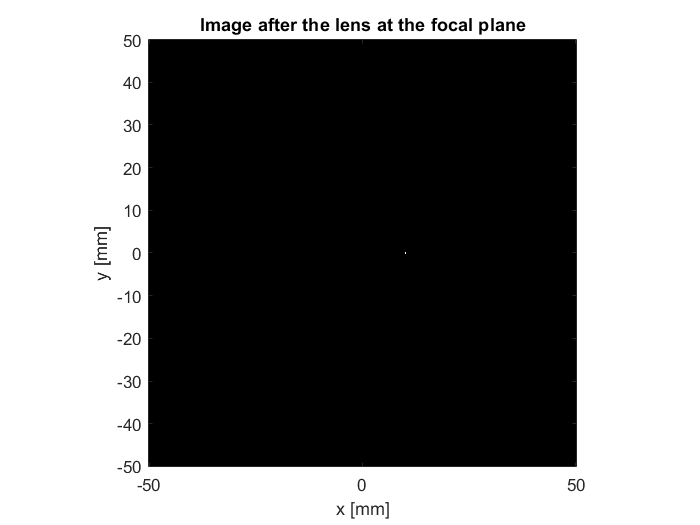

I2 = E2.*conj(E2);
figure;  colormap(gray);
imagesc(x2*1e3,y2*1e3,I2');
set(gca,'ydir','normal');
axis image;
xlabel('x [mm]');  ylabel('y [mm]');
title('Image after the lens at the focal plane');